clear
close all 

s=0;
while s~=1 & s~=2
    s=input('Gravar audio(1) ou carregar arquivo(2)? ');
end

if s==1
    TxAmost=8000; %Hz
    Bits_Amostra=16;
    Tempo_Gravacao=4; %segundos
    disp(['Taxa de amostragem =  ',num2str(TxAmost),' Hz'])
    disp(['Bits/amostra =  ',num2str(Bits_Amostra)])
    disp(['Tempo de gravacao = ',num2str(Tempo_Gravacao),' segundos'])
        
    
    recObj = audiorecorder(TxAmost,Bits_Amostra,1);

%Common sample rates are 8000, 11025, 22050, 44100, 48000, and 96000 Hz.
%The number of bits must be 8, 16, or 24. The number of channels must
% be 1 or 2 (mono or stereo).

    disp('Comece a falar')
    recordblocking(recObj, Tempo_Gravacao);
    disp('Fim da gravacao.');

    disp('Reproducao do audio gravado')
    play(recObj);
    pause(Tempo_Gravacao)
    
    y = getaudiodata(recObj);
    
    s=input('Deseja armazenar o arquivo gerado? [s/n] ','s');
    
    if s=='s'
        save joao.mat y TxAmost Bits_Amostra Tempo_Gravacao
    end
    

else
    load nomedoarquivo.mat
    
    disp(['Taxa de amostragem =  ',num2str(TxAmost),' Hz'])
    disp(['Bits/amostra =  ',num2str(Bits_Amostra)])
    disp(['Tempo de gravacao = ',num2str(Tempo_Gravacao),' segundos'])
    
    disp('Reproducao do audio gravado')
    player = audioplayer(y,TxAmost);
    play(player);
    pause(Tempo_Gravacao)
end

Taxa de amostragem =  8000 Hz


Bits/amostra =  16


Tempo de gravacao = 4 segundos


Comece a falar


Fim da gravacao.


Reproducao do audio gravado


    
    % quantizando o audio
    [Yamost,delta,SNR] = quantizador(y,5);
    
    disp('Reproducao do audio quantizado')

Reproducao do audio quantizado


    player = audioplayer(Yamost,TxAmost);
    play(player);
    pause(Tempo_Gravacao)

    % mod delta
    Deltam1 = modudelta(y,0.05);
    
    disp('Reproducao do audio mod delta')  

Reproducao do audio mod delta


    player = audioplayer(Deltam1,TxAmost);
    play(player);
    pause(Tempo_Gravacao) 
    



disp('Gerando figuras ...')

Gerando figuras ...


## Gráfico do sinal no tempo

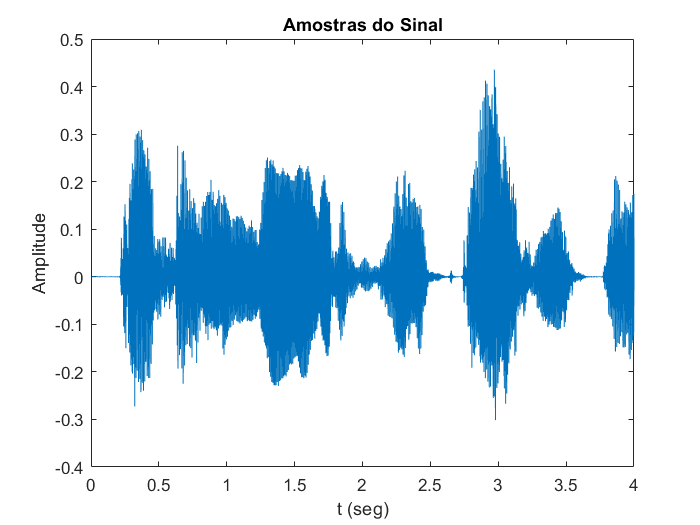

figure(1)
t=0:1/TxAmost:(length(y)-1)/TxAmost;
plot(t,y);
xlabel('t (seg)')
ylabel('Amplitude')
title('Amostras do Sinal')

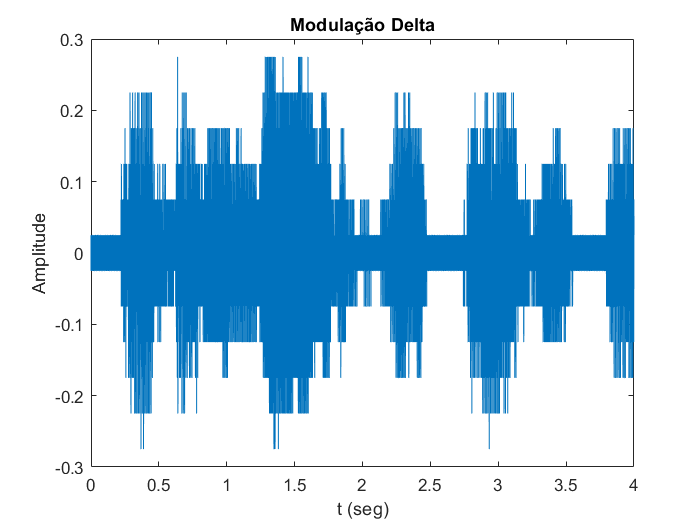



figure(2)
t=0:1/TxAmost:(length(y)-1)/TxAmost;
plot(t,Deltam1);
xlabel('t (seg)')
ylabel('Amplitude')
title('Modulação Delta')

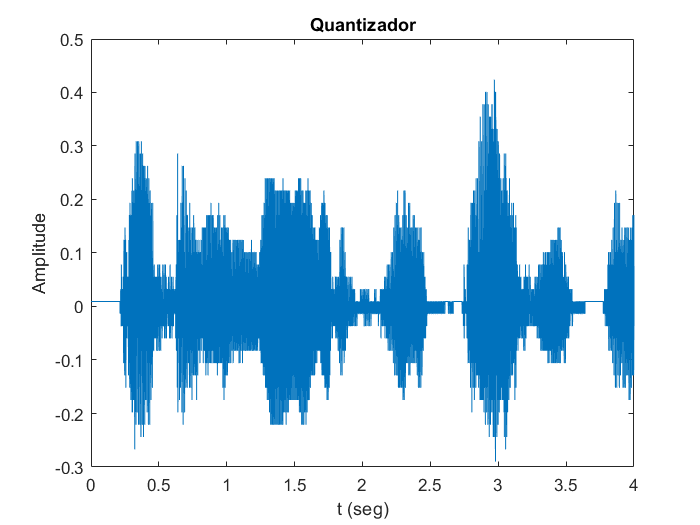


figure(3)
t=0:1/TxAmost:(length(y)-1)/TxAmost;
plot(t,Yamost);
xlabel('t (seg)')
ylabel('Amplitude')
title('Quantizador')

## Eliminando componentes nulas iniciais

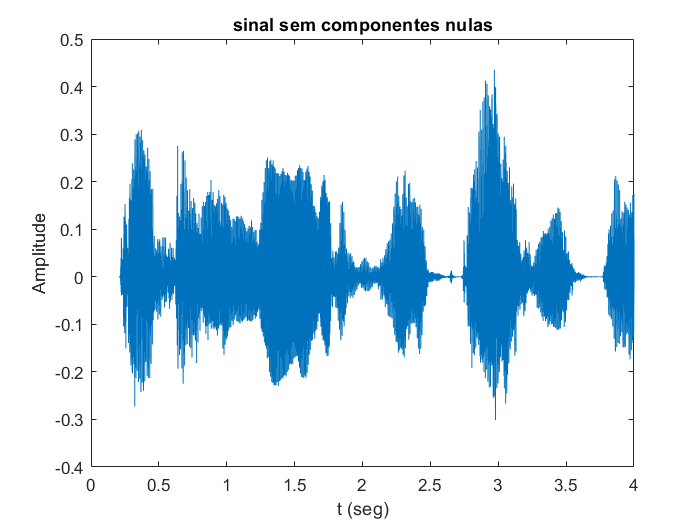

for k = 1: length(y)% Acha o k que inicia a voz
    if sign(20*2/2^(Bits_Amostra) - abs(y(k)) ) < 0
        break
    end
end

figure(3)
t=(k-1)/TxAmost:1/TxAmost:(length(y)-1)/TxAmost;
plot(t,y(k: end ));
xlabel('t (seg)')
ylabel('Amplitude')
title('sinal sem componentes nulas')

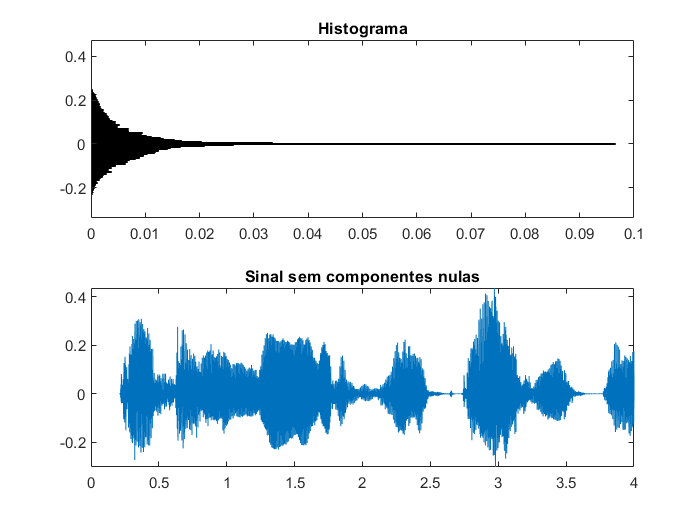


figure(4)
subplot(2,1,1)
histogram(y(k:end),2^8,'orientation',"horizontal",'Normalization',"probability");
title('Histograma')
subplot(2,1,2)
t=(k-1)/TxAmost:1/TxAmost:(length(y)-1)/TxAmost;
plot(t,y(k: end ));
title('Sinal sem componentes nulas')

## Espectro de amplitudes do sinal

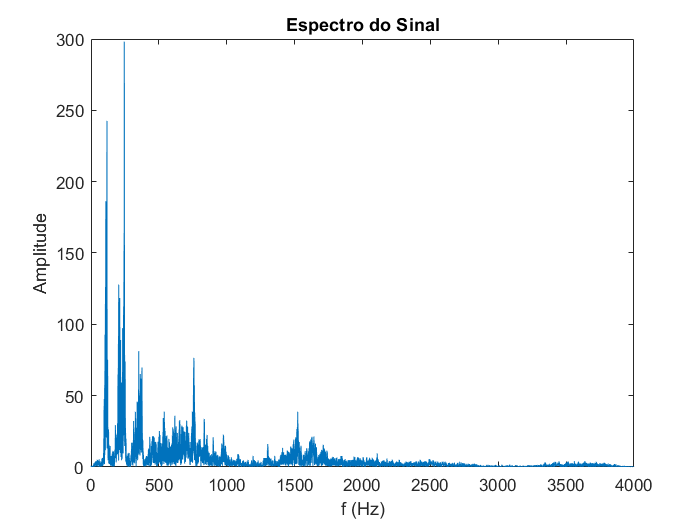

Lfft = 2^ceil(log2(length(y)));% melhora o algoritmo
Y=fft(y,Lfft);

Fmax=TxAmost/2 ;
Faxis=linspace(0,Fmax,Lfft/2);


figure(2)
plot(Faxis,abs(Y( 1:floor(length(Y)/2) )))
xlabel('f (Hz)')
ylabel('Amplitude')
title('Espectro do Sinal')

## Passando o sinal por um filtro passa-baixas

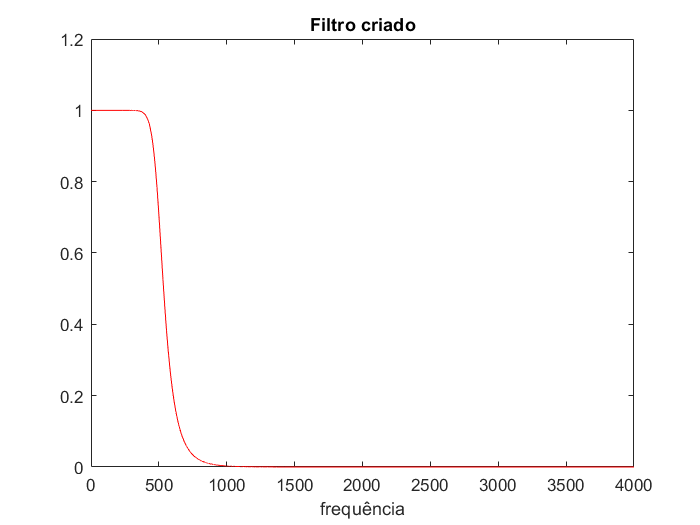

fc=500; %freq. de corte
Wn=fc/(TxAmost/2); %normalizando a freq de corte   

% O filtro butterworth usa a freq de corte normalizada com a freq de
% nyquist. ( nyquistrate/2 )

[b,a] = butter(8,Wn);% criação do filtro butterworth de grau 8
[H,W] = freqz(b,a,length(f));
figure(6)
plot(f,abs(H),'r')
title('Filtro criado')
xlabel('frequência')


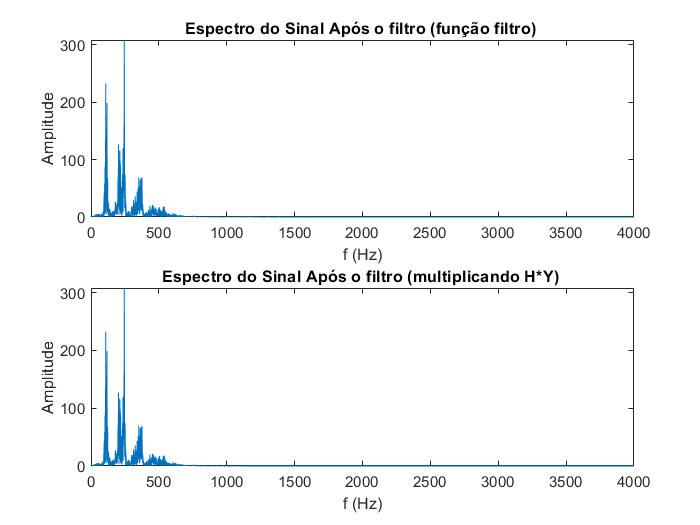


y_filt=filter(b,a,y); %realiza a filtragem


Y_filt=fft(y_filt);

figure(5)
subplot(2,1,1)
plot(f,abs(Y_filt(1:floor(length(Y_filt)/2))))
title('Espectro do Sinal Após o filtro (função filtro) ')
xlabel('f (Hz)')
ylabel('Amplitude')

subplot(2,1,2)
plot(f,abs(H(1:floor(length(Y_filt)/2)).*Y(1:floor(length(Y_filt)/2))))
title('Espectro do Sinal Após o filtro (multiplicando H*Y) ')
xlabel('f (Hz)')
ylabel('Amplitude')



disp('Reproduzindo o audio filtrado')
player = audioplayer(y_filt,TxAmost);

Reproduzindo o audio filtrado


play(player);

